Definitionen:

signal_1 = [-1,1,-1,1];
signal_2 = [-1,1,1,-1];


f = -1000:1:1000;

signal_length = 20;

rand_sig_1 = round(0.75*rand(1,signal_length));
rand_sig_2 = round(0.75*rand(1,signal_length));

user_1_code = 1; %Nutzer
user_2_code = 2; %Nutzer

codelength = 4; %nur werte 2^n

Encode Signals And Mix im Basisband

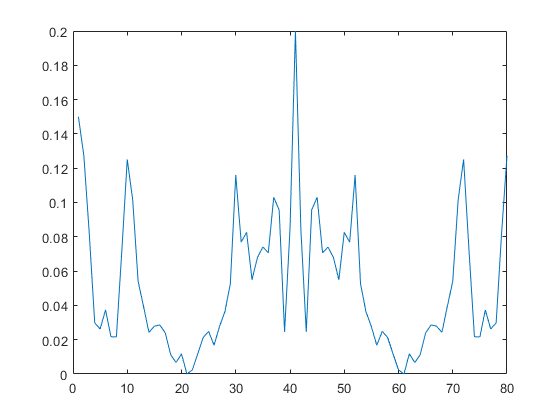

encoded_sig_1 = CDMA_Encoder(rand_sig_1,user_1_code,codelength);
encoded_sig_2 = CDMA_Encoder(rand_sig_2,user_2_code,codelength);

resulting_sig = encoded_sig_2+encoded_sig_1;

plot(abs(fftshift(fft(resulting_sig)))/length(resulting_sig));

Decode Signals from mixxed Band

decoded_sig_1 = CDMA_Decoder(resulting_sig,user_1_code,codelength,signal_length)

decoded_sig_1 =      1    -1    -1    -1    -1     1    -1    -1    -1    -1    -1    -1    -1    -1     1    -1    -1    -1     1    -1


decoded_sig_2 = CDMA_Decoder(resulting_sig,user_2_code,codelength,signal_length)

decoded_sig_2 =     -1    -1     1    -1     1    -1     1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1
